# OGLO notebook 4g

hnxj@github

## Spectrolaminar analysis

V1

nPath = "lfpData\";
nFiles = {dir(nPath).name};
nFiles = nFiles(endsWith(nFiles, ".mat"));

z = cell(1, 10);

for i = 1:4

    nFile = nFiles{i};
    z{i} = load(nPath + nFile).z;
    disp(num2str(i) + ". loaded : " + nFile);

end

1. loaded : 01_LFPs_OGLO_V1.mat
2. loaded : 02_LFPs_OGLO_V2.mat
3. loaded : 03_LFPs_OGLO_V3a.mat
4. loaded : 04_LFPs_OGLO_V3d.mat


xG = z{1}; % Struct; 

y = squeeze(mean(mean(xG{1}{1}, 1), 2));
[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
pgcx1 = zeros([12, 64, size(p1)]);

for ik = 1:12% condition

    xG1 = xG{ik};

    for jk = 1:size(xG1, 2) % sessions; skip if you only have 1 session

        xG2 = xG1{jk};

        for kk = 1:size(xG2, 1) % trials

            CH = size(xG2, 2);

            for lk = 1:CH % channels

                y = squeeze(xG2(kk, lk, :));
                y = y - mean(y) / std(y);
                y(isinf(y)) = 0;
                y(isnan(y)) = 0;
                [p1temp, f, t] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
                pgcx1(ik, lk, :, :) = squeeze(pgcx1(ik, lk, :, :)) + p1temp;
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

cond : 1
cond : 2
cond : 3
cond : 4
cond : 5
cond : 6
cond : 7
cond : 8
cond : 9
cond : 10
cond : 11
cond : 12


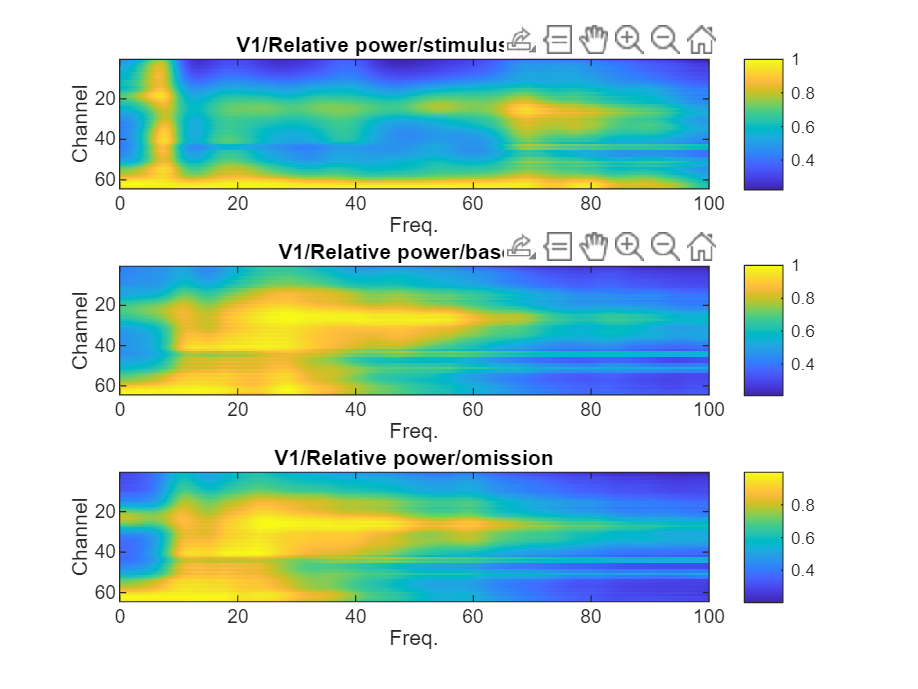

figure;
imx1 = squeeze(mean(pgcx1(12, :, :, 23:30), 4));
for ik = 1:size(imx1, 2)

    imx1(:, ik) = smooth(imx1(:, ik), 4) / max(imx1(:, ik));

end
subplot(3, 1, 1);
imagesc(imx1, "XData", f1);colorbar;xlabel("Freq.");
ylabel("Channel");title("V1/Relative power/stimulus present");

imx2 = squeeze(mean(pgcx1(12, :, :, 9:19), 4));
for ik = 1:size(imx2, 2)

    imx2(:, ik) = smooth(imx2(:, ik), 4) / max(imx2(:, ik));

end

subplot(3, 1, 2);
imagesc(imx2, "XData", f1);colorbar;xlabel("Freq.");
ylabel("Channel");title("V1/Relative power/baseline");

imx3 = squeeze(mean(pgcx1(12, :, :, 94:110), 4));
for ik = 1:size(imx3, 2)

    imx3(:, ik) = smooth(imx3(:, ik), 4) / max(imx3(:, ik));

end

subplot(3, 1, 3);
imagesc(imx3, "XData", f1);colorbar;xlabel("Freq.");
ylabel("Channel");title("V1/Relative power/omission");

## V2

xG = z{2};

y = squeeze(mean(mean(xG{1}{1}, 1), 2));
[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
pgcx2 = zeros([12, 64, size(p1)]);

for ik = 1:12% condition

    xG1 = xG{ik};

    for jk = 1:size(xG1, 2) % sessions

        xG2 = xG1{jk};

        for kk = 1:size(xG2, 1) % trials

            CH = size(xG2, 2);

            for lk = 1:CH % channels

                y = squeeze(xG2(kk, lk, :));
                y = y - mean(y) / std(y);
                y(isinf(y)) = 0;
                y(isnan(y)) = 0;
                [p1temp, f, t] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
                pgcx2(ik, lk, :, :) = squeeze(pgcx2(ik, lk, :, :)) + p1temp;
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

cond : 1
cond : 2
cond : 3
cond : 4
cond : 5
cond : 6
cond : 7
cond : 8
cond : 9
cond : 10
cond : 11
cond : 12


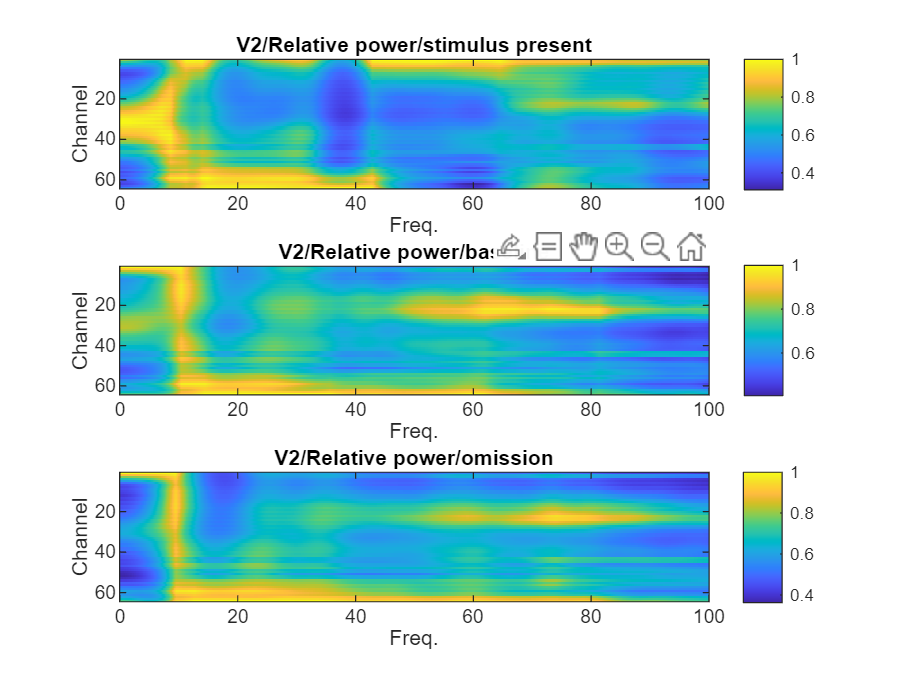

figure;
imx1 = squeeze(mean(pgcx2(12, :, :, 23:30), 4));
for ik = 1:size(imx1, 2)

    imx1(:, ik) = smooth(imx1(:, ik), 4) / max(imx1(:, ik));

end
subplot(3, 1, 1);
imagesc(imx1, "XData", f1);colorbar;xlabel("Freq.");
ylabel("Channel");title("V2/Relative power/stimulus present");

imx2 = squeeze(mean(pgcx2(12, :, :, 9:19), 4));
for ik = 1:size(imx2, 2)

    imx2(:, ik) = smooth(imx2(:, ik), 4) / max(imx2(:, ik));

end

subplot(3, 1, 2);
imagesc(imx2, "XData", f1);colorbar;xlabel("Freq.");
ylabel("Channel");title("V2/Relative power/baseline");

imx3 = squeeze(mean(pgcx2(12, :, :, 94:110), 4));
for ik = 1:size(imx3, 2)

    imx3(:, ik) = smooth(imx3(:, ik), 4) / max(imx3(:, ik));

end

subplot(3, 1, 3);
imagesc(imx3, "XData", f1);colorbar;xlabel("Freq.");
ylabel("Channel");title("V2/Relative power/omission");